# Obligatorisk oppgave 1

Skrevet av Mats Hoem Olsen (107906)

## Oppgave 1

T = [1,1,1];
n = 20;
for t = 4:n
    T(t) = T(t-1) + T(t-2) + T(t-3);
end  
disp(T)

  Columns 1 through 10

           1           1           1           3           5           9          17          31          57         105

  Columns 11 through 20

         193         355         653        1201        2209        4063        7473       13745       25281       46499



Ved forskjellige verdier av n får vi en vektor mel lengde n med tall som følger formelen F(n) = F(n-1)+F(n-2)+F(n-3).

## Oppgave 2

I denne oppgaven leker vi en lek hvor to stykke (A og B) spiller om å vinne poeng ved å trekke 2 tilfelldige tall. Antall forsøk er antall poeng vinneren får. Her er oppsettet.

teller = 0;
sum = 0;
A = true; %Spiller A
terskelverdi = 1.9;
while sum <= terskelverdi % Erstatt ... med betingelsen som må være oppfylt for at vi skal trekke nye tall i while-løkka
    sum = rand(1)+rand(1);
    teller = teller + 1;      % Erstatt ... med en beregning som sørger for at opptellingen blir korrekt.
    if mod(teller,2) == 0
        A = not(A); %skifter tur
    end
end
display(teller);

teller = 8

display(not(turn)) %Vinner

  logical

   0



Dette er bare en runde. Nå utvider vi dette.

A_sum = 0;
B_sum = 0;
runder = 0;
while not(or(A_sum > 1000, B_sum > 1000))
    teller = 0;
    sum = 0;
    A = true; %Spiller A
    terskelverdi = 1.9;
    while sum <= terskelverdi % Erstatt ... med betingelsen som må være oppfylt for at vi skal trekke nye tall i while-løkka
        sum = rand(1)+rand(1);
        if mod(teller,2) == 0
          A = not(A); %skifter tur
        end
        teller = teller + 1;
    end
    runder = runder + 1;
    if not(A)
        B_sum = B_sum + teller;
    else 
        A_sum = A_sum + teller;
    end
end
disp("B score: " + string(B_sum))

B score: 1090


disp("A score: " + string(A_sum))

A score: 719


disp("Runder: " + string(runder))

Runder: 14


I dette tilfelle vant B. Dette er ikke det mest underholdende spillet i verden men viser at tilfeldigheter kan variere.

## Oppgave 3

I denne oppgaven bestemmer vi parringsmønsteret til kanninene. Hvor hver måned trekker vi et tilfelldig tall fra intervallet [0,1), hvis verdien er over terskelen så får de pare, ellers fjerner vi kaniner. 

n = 10;         % Antall måneder (denne kan du godt endre på og kjøre koden på nytt)
terskelverdi = 0.1;
F = zeros(n,1); % F er vektoren hvor vi lagrer alle de n Fibonacci-tallene etter hvert som de beregnes.
F(1) = 1;
F(2) = 1;
for k = 3:n % Legg merke til at siden de to første tallene er oppgitt så starter vi med å beregne det tredje.
    r = rand(1); % Vi trekker et tilfeldig tall
    if r > terskelverdi
        F(k) = F(k-1) + F(k-2);  % Erstatt ... med den korrekte oppdateringen
    else
        F(k) = F(k-1) - F(k-2); % Erstatt ... med den korrekte oppdateringen
    end
    if F(k) <= 0 %Skjekker om vi har kaninger
        disp("Kaninarten er utryddet")
        break %Avbryter loopen siden vi i praksis har ingen kaniner
    end
end
disp(F)

     1
     1
     2
     3
     5
     8
    13
     5
    18
    23



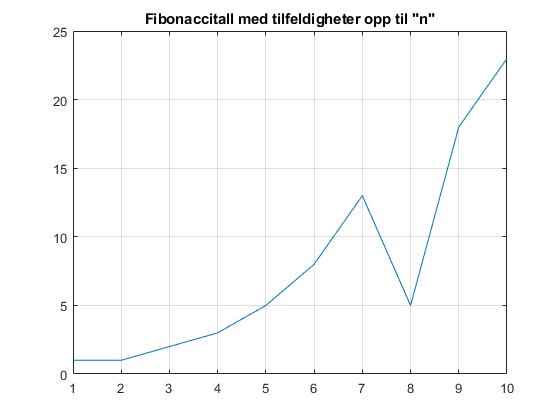

figure, plot(F), grid
title('Fibonaccitall med tilfeldigheter opp til "n"')

Vi kan se fra grafen at dette påvirker ikke veksten enormt. 

## Oppgave 4

Dette programmet lager en vektor M med størrelse n, som inneholder produktet av indexene j, og i . 

n = 100;
%funksjonen
if n < 0
    disp("error, n<0")
    M = 0;
    return
end
M = zeros(n,n); % Her opprettes tabellen M og fylles med 0-er.

for i = 1:n % Fyll inn det som er nødvendig
       for j = 1:n % Fyll inn det som er nødvendig
           M(i,j) = i*j;
       end
end
%ikke funksjonen
M = Fuky(100);
M(68,88)

ans = 5984

K = Fuky(-5)

error, n<0


K = 0

På siste linje får vi en feil siden n < 0 og kan derfor ikke produsere en tabell. 